# Photosynthesis-irradiance Curve

## Get the P-I data

containerdir = ['/Users/Danny/Desktop/CATEGORIES/CAREER_MANAGEMENT/VIMS/'...
            'Assistance/Helga_do_Rosario_Gomes/'];
datafile = [containerdir,'PE_Dan2016.csv'];

PIdata = readtable(datafile);

## Examine the data

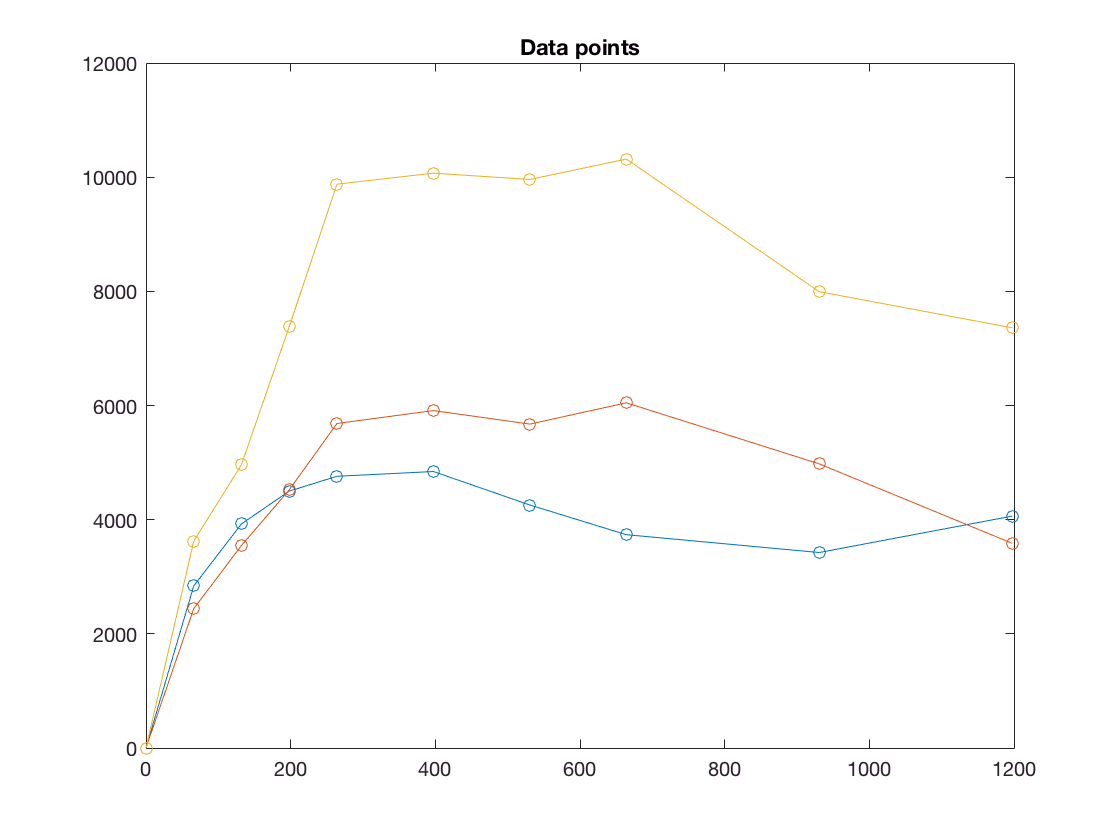

E  = PIdata.E;
y1 = PIdata.control_P_;
y2 = PIdata.Peridinuim_P_;
y3 = PIdata.Phaeodactylum_P_;
% axis([0 2 -0.5 6])
% hold on
plot(E,[y1,y2,y3], 'marker','o', 'linestyle','-')
title('Data points')

## Platt Equation:


$$$$


Let's define the parameters in terms of a single variable "x"

x(1) = PBs;

x(2) = alpha;

x(3) = beta;

Then we'll define the platt curve as a function of the parameter vector "x" and the irradiance data, which will enter the function as "xdata"

F = @(x,xdata)x(1) * (1-exp( (-x(2)*xdata)/x(1) ) ) .* exp( (-x(3)*xdata)/x(1) )

F =     @(x,xdata)x(1)*(1-exp((-x(2)*xdata)/x(1))).*exp((-x(3)*xdata)/x(1))


We need to set a starting point for the optimization routine... here we'll use PBs=1.07, alpha=0.03, beta = 0.00:

x0 = [1070 550 0.00];

We run the solver and plot the resulting fit.

[x,resnorm,~,exitflag,output] = lsqcurvefit(F,x0,E,y1)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



x =    1.0e+03 *

    5.1422    0.0656    0.0016


resnorm = 8.1130e+05

exitflag = 3

output =     firstorderopt: 1.7949
       iterations: 33
        funcCount: 136
     cgiterations: 0
        algorithm: 'trust-region-reflective'
         stepsize: 0.0421
          message: 'Local minimum possible.…'


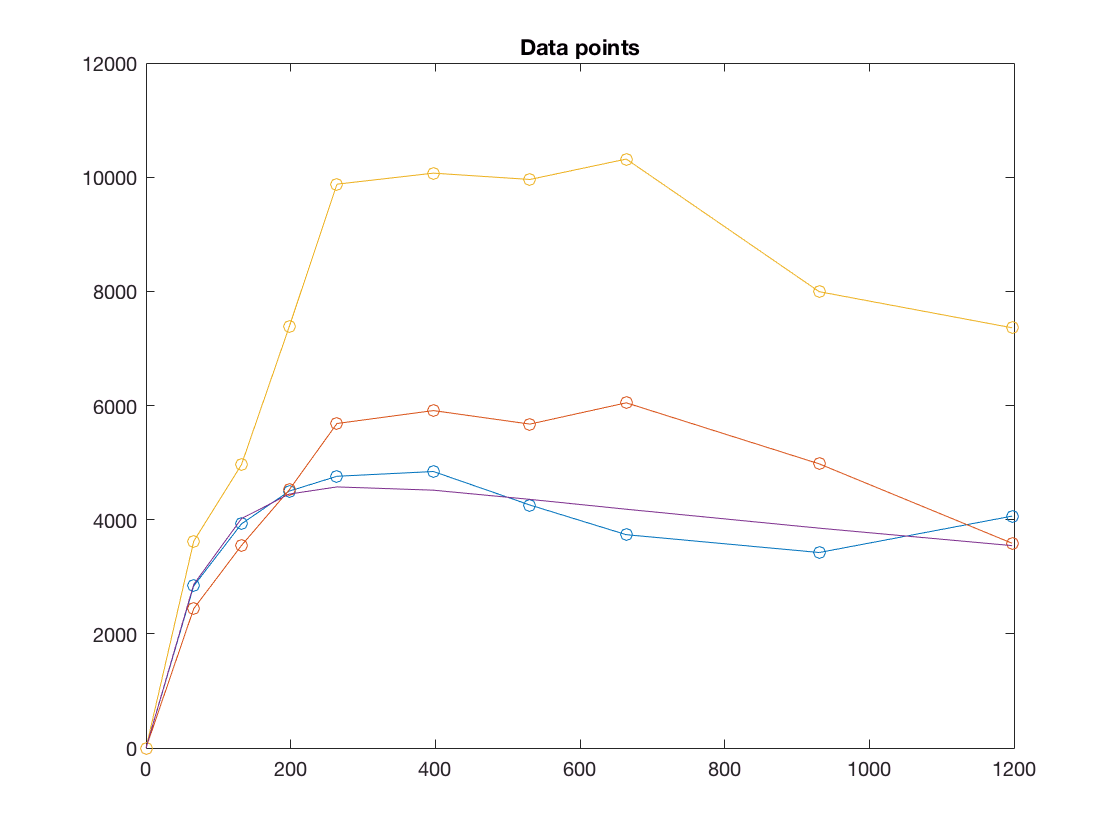

hold on
plot(E,F(x,E), 'b--')
hold off

[x,resnorm,~,exitflag,output] = lsqcurvefit(F,x0,E,y2)
hold on
plot(E,F(x,E), 'r--')

[x,resnorm,~,exitflag,output] = lsqcurvefit(F,x0,E,y3)
hold on
plot(E,F(x,E), 'y--')